# Introduction to MATLAB: Basic Functions, Loops, and Arrays

% 1. Variables and Arithmetic
a = 10; % Scalar variable
b = 5;  % Another scalar variable

% Basic arithmetic operations
sum_ab = a + b; % Addition
diff_ab = a - b; % Subtraction
prod_ab = a * b; % Multiplication
div_ab = a / b; % Division

% Display results
fprintf('Sum: %d, Difference: %d, Product: %d, Division: %.2f\n', sum_ab, diff_ab, prod_ab, div_ab);

Sum: 15, Difference: 5, Product: 50, Division: 2.00


## 2. Arrays (Vectors and Matrices)

x = [1, 2, 3, 4, 5]; % Row vector
y = [10; 20; 30; 40; 50]; % Column vector (5x1 matrix)

% Array operations
sum_x = sum(x); % Sum of all elements in x
mean_y = mean(y); % Mean of all elements in y

fprintf('Sum of x: %d, Mean of y: %.2f\n', sum_x, mean_y);

Sum of x: 15, Mean of y: 30.00


## 3. For Loop: Calculating Square of Numbers

n = 10; % Number of iterations
squares = zeros(1, n); % Pre-allocate array for storing squares

for i = 1:n
    squares(i) = i^2; % Square of each number from 1 to n
end

% Display the squares
disp('Squares of numbers from 1 to 10:');

Squares of numbers from 1 to 10:


disp(squares);

     1     4     9    16    25    36    49    64    81   100



## 4. If-Else Conditional Statements

threshold = 25; % Define a threshold

if sum_ab > threshold
    fprintf('The sum %d is greater than the threshold %d.\n', sum_ab, threshold);
else
    fprintf('The sum %d is less than or equal to the threshold %d.\n', sum_ab, threshold);
end

## 5. Plotting: Sine and Cosine Functions

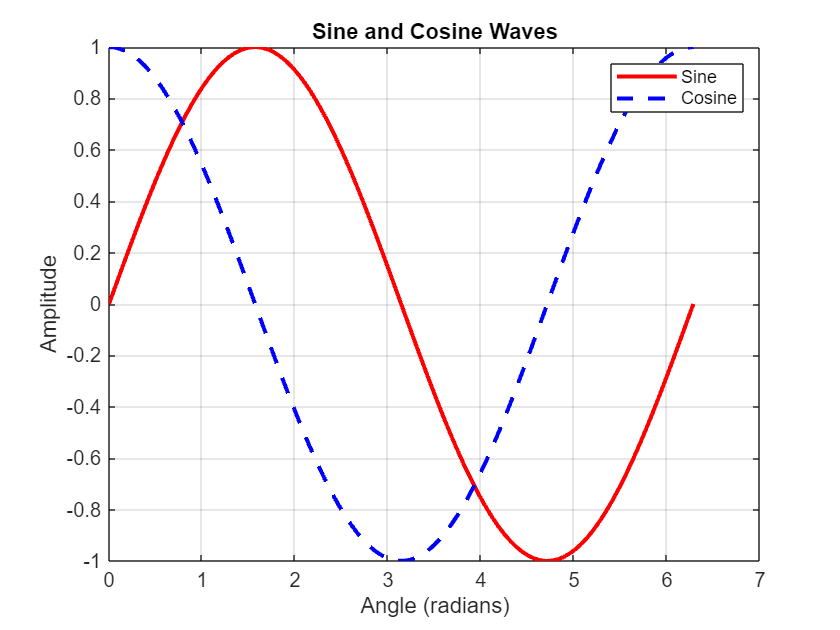

theta = linspace(0, 2*pi, 100); % Create an array of 100 points between 0 and 2π
sine_wave = sin(theta); % Sine function
cosine_wave = cos(theta); % Cosine function

% Create the plot
figure;
plot(theta, sine_wave, 'r', 'LineWidth', 2); % Plot sine in red
hold on;
plot(theta, cosine_wave, 'b--', 'LineWidth', 2); % Plot cosine in blue, dashed line
hold off;

% Add labels and title
xlabel('Angle (radians)');
ylabel('Amplitude');
title('Sine and Cosine Waves');
legend('Sine', 'Cosine');
grid on;





%**************************************************************************************************************

## Simple Electric Vehicle Model in MATLAB

clear
clc

% Parameters
vehicle_mass = 1500; % Mass of the vehicle in kg
drag_coefficient = 0.3; % Aerodynamic drag coefficient (dimensionless)
frontal_area = 2.2; % Frontal area in m^2
rolling_resistance_coefficient = 0.015; % Rolling resistance coefficient (dimensionless)
air_density = 1.225; % Air density in kg/m^3
gravitational_acceleration = 9.81; % Gravity in m/s^2

% Driving Parameters
speed = 25; % Vehicle speed in m/s (~90 km/h)
distance = 10000; % Distance traveled in meters (10 km)
road_slope = 0; % Road slope (degrees)

% Power Calculations
% 1. Aerodynamic Drag Force
drag_force = 0.5 * air_density * drag_coefficient * frontal_area * speed^2;

% 2. Rolling Resistance Force
rolling_resistance = vehicle_mass * gravitational_acceleration * rolling_resistance_coefficient * cosd(road_slope);

% 3. Gravitational Force (if slope is present)
gravitational_force = vehicle_mass * gravitational_acceleration * sind(road_slope);

% 4. Total Force
total_force = drag_force + rolling_resistance + gravitational_force;

% 5. Power Required (P = F * v)
power_required = total_force * speed; % in Watts

% 6. Energy Consumption (E = P * t)
time = distance / speed; % Time in seconds
energy_consumed = power_required * time / 3600; % Energy in Watt-hours (Wh)

% Display results
fprintf('Total energy consumed for a %.2f km trip: %.2f Wh\n', distance / 1000, energy_consumed);

% Plotting Energy vs Speed
speeds = linspace(5, 40, 100); % Speed range in m/s
energy_consumption = zeros(1, length(speeds));

for i = 1:length(speeds)
    % Recalculate forces and power for each speed
    drag_force_i = 0.5 * air_density * drag_coefficient * frontal_area * speeds(i)^2;
    total_force_i = drag_force_i + rolling_resistance + gravitational_force;
    power_required_i = total_force_i * speeds(i);
    time_i = distance / speeds(i);
    energy_consumption(i) = power_required_i * time_i / 3600;
end

% Plot
figure;
plot(speeds * 3.6, energy_consumption, 'LineWidth', 2); % Convert speed to km/h
xlabel('Speed (km/h)');
ylabel('Energy Consumption (Wh)');
title('Energy Consumption vs Speed');
grid on;